1.绘制刺激位置

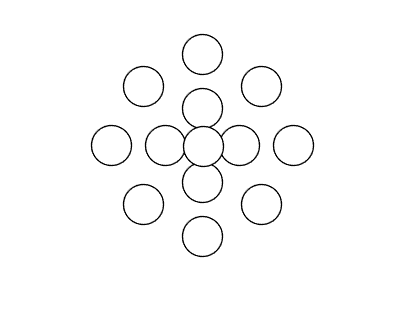

load('D:\\Ensemble coding\\data\\patch_location.mat');
figure;
% 创建一个241x241的黑色图片
image = ones(241, 241);

% 将图片显示出来
imshow(image);

% 保持图像窗口打开，以便在上面绘制
hold on;

% 设置圆的中心坐标和半径
radius = 20;
for i = 1:13
    r = rectangle('Position',[location(i,1) - radius, location(i,2) - radius, radius * 2, radius * 2]);
    r.FaceColor = 'w';    % 填充颜色，可以采用'none'，[0 .5 .5]
    r.Curvature = [1,1];     % 圆角  
    r.EdgeColor = 'k';       % 边缘颜色
    r.LineWidth = 1;         % 线粗
    r.LineStyle = "-";       % 线的类型
    axis equal; 
end

%position的输入是左下角的点的坐标，以及两个横纵分量的值
% 释放图像窗口
%hold off;

2.绘制感受野

load('D:\\Ensemble coding\\data\\SPN-DG2_u759-010.mat');
load('D:\\Ensemble coding\\data\\chanmap.mat');
% 刺激中心位置 （-2，-1.5）
% 注视点（5，3）,新的感受野图中的注视点是（0，1）；
% 注视点对齐到（0，0），所以刺激中心位置会变为（-7，-4.5）
% 所以左上角会变为（-9，-2.5）
sticenter = [-4, -0.5];
%先把感受野位置与刺激中心位置对齐
xlocation = SPNLY.xlocation - sticenter(1);
ylocation = SPNLY.ylocation - sticenter(2);
%按照每一度为60像素，
xlocation = xlocation*60;
ylocation = abs(ylocation)*60;
%这里要注意每个感受野的位置的标签是实际的，而不是按照1-100顺序的。
clusterColor = {
    '#7BB69B';
    '#44BBD1';
    '#F4CB68';
    '#196087';
    '#D15039';}

clusterColor = 5×1 cell 数组
    {'#7BB69B'}
    {'#44BBD1'}
    {'#F4CB68'}
    {'#196087'}
    {'#D15039'}


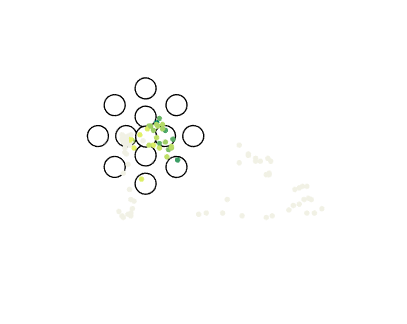


%clusteridx = find(ST.T == cluster);
cluster =1:96;
for i = cluster
    
    m = find(ChanMap==i);
    RF_randius = SPNLY.radius(m)*60;
    r = rectangle('Position',[xlocation(m) - 1, ylocation(m) - 1, 4 * 2, 4 * 2]);
    %r = rectangle('Position',[xlocation(m) - RF_randius, ylocation(m) - RF_randius, RF_randius * 2, RF_randius * 2]);
    r.FaceColor = coilcolormap(floor(coilSNR(i)/20*256)-1,:);    % 填充 颜色，可以采用'none'，[0 .5 .5]
    r.Curvature = [1,1];     % 圆角  
    %r.EdgeColor = clusterColor{1};
    r.EdgeColor = coilcolormap(floor(coilSNR(i)/20*256)-1,:);       % 边缘颜色
    r.LineWidth = 1;         % 线粗
    r.LineStyle = "-";       % 线的类型
    axis equal; 
    %text(xlocation(m), ylocation(m), num2str(i), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', 'FontSize', 12, 'Color', 'r');
end
hold off;

3.电极地形图

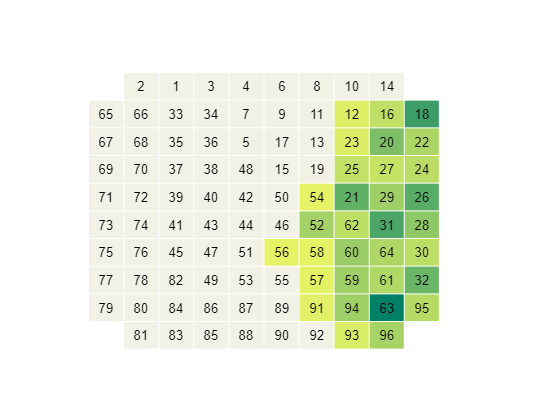

% 创建一个10x10的网格
figure;

[X, Y] = meshgrid(1:10, 1:10);

% 计算每个方格的中心坐标
Xcenter = X ;
Ycenter = Y ;

% 创建一个10x10的方格图
figure;
hold on;
for i = 1:10
    for j = 1:10
        % 绘制方格
        m = rectangle('Position', [j-0.5, i-0.5, 1, 1], 'EdgeColor', 'w');
        if chanmap(11-i,j) <= 96
            % m.FaceColor = clusterColor{ST.T(chanmap(11-i,j))};
            m.FaceColor =coilcolormap(floor(coilSNR(chanmap(11-i,j))/20*256)-1,:);
            text(Xcenter(i,j), Ycenter(i,j), num2str(chanmap(11-i,j)), ...
            'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle');
        else
            m.FaceColor = 'none';
        end

        % 在方格中心添加文字标签
        
    end
end
axis off
hold off;